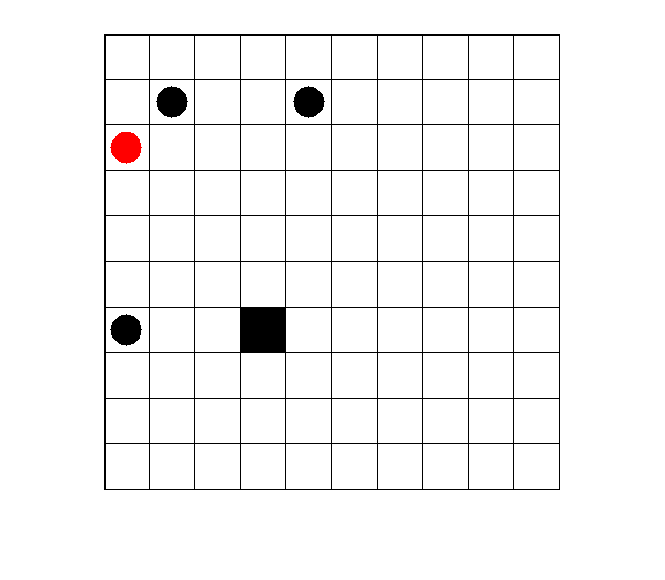

% Define the size of the grid
gridSize = 10; % Adjust this value to change the size of the grid

% Create a binary matrix representing the presence (1) or absence (0) of a black circle
playgorund_matrix = zeros(gridSize);

% Set the indices where you want to place a black circle
playgorund_matrix(1, 3) = 2; % Adjust these indices as needed
playgorund_matrix(2,2) = 1;
playgorund_matrix(4,7) = 1;
playgorund_matrix(5, 2) = 1; % Adjust these indices as needed
playgorund_matrix(7,2) = 6;
playgorund_matrix(1,7) = 1;

% Create a blank image with white background
imageSize = 500; % Adjust this value to change the size of the image
blankImage = ones(imageSize, imageSize, 3);

% Calculate the size of each grid cell
cellSize = imageSize / gridSize;

% Create a meshgrid for the rows and columns
[rows, cols] = meshgrid(1:imageSize, 1:imageSize);

% Iterate through the matrix and draw circles where the value is 1
for i = 1:gridSize
    for j = 1:gridSize
        if playgorund_matrix(i, j) == 1
            % Calculate the position of the circle in the image
            circleX = round((j - 1) * cellSize + cellSize / 2);
            circleY = round((i - 1) * cellSize + cellSize / 2);

            % Calculate the radius of the circle
            circleRadius = round(cellSize / 3);

            % Create a binary mask for the circle
            circleMask = (rows - circleY).^2 + (cols - circleX).^2 <= circleRadius.^2;

            % Set the color of the circle to black (RGB = [0, 0, 0])
            blankImage(repmat(circleMask, [1, 1, 3])) = 0;
        end


        if playgorund_matrix(i,j) ==2
            % Calculate the position of the circle in the image
            circleX = round((j - 1) * cellSize + cellSize / 2);
            circleY = round((i - 1) * cellSize + cellSize / 2);

            % Calculate the radius of the circle
            circleRadius = round(cellSize / 3);

            % Create a binary mask for the circle
            circleMask = (rows - circleY).^2 + (cols - circleX).^2 <= circleRadius.^2;

            % Set the color of the circle to red (RGB = [1, 0, 0])
            blankImage(repmat(circleMask, [1, 1, 3])) = repmat([1, 0, 0], [sum(circleMask(:)), 1]);
        end

        if playgorund_matrix(i,j) ==3
            % Calculate the position of the circle in the image
            circleX = round((j - 1) * cellSize + cellSize / 2);
            circleY = round((i - 1) * cellSize + cellSize / 2);

            % Calculate the radius of the circle
            circleRadius = round(cellSize / 3);

            % Create a binary mask for the circle
            circleMask = (rows - circleY).^2 + (cols - circleX).^2 <= circleRadius.^2;

            % Set the color of the circle to red (RGB = [1, 0, 0])
            blankImage(repmat(circleMask, [1, 1, 3])) = repmat([0, 1, 0], [sum(circleMask(:)), 1]);
        end

        
        if playgorund_matrix(i,j) ==5
            % Calculate the position of the circle in the image
            circleX = round((j - 1) * cellSize + cellSize / 2);
            circleY = round((i - 1) * cellSize + cellSize / 2);

            % Calculate the radius of the circle
            circleRadius = round(cellSize / 3);

            % Create a binary mask for the circle
            circleMask = (rows - circleY).^2 + (cols - circleX).^2 <= circleRadius.^2;

            % Set the color of the circle to red (RGB = [1, 0, 0])
            blankImage(repmat(circleMask, [1, 1, 3])) = repmat([1, 0, 1], [sum(circleMask(:)), 1]);
        end


        % Set the color of the square to black
        if playgorund_matrix(i, j) == 6
            % Calculate the position of the square in the image
            squareX = round((squareCol - 1) * cellSize + cellSize / 2);
            squareY = round((squareRow - 1) * cellSize + cellSize / 2);
        
            % Calculate the size of the square
            squareSize = round(cellSize);
        
            % Create a binary mask for the square
            squareMask = rows >= squareY - squareSize / 2 & rows <= squareY + squareSize / 2 & ...
                          cols >= squareX - squareSize / 2 & cols <= squareX + squareSize / 2;
        
            % Set the color of the square to black (RGB = [0, 0, 0])
            blankImage(repmat(squareMask, [1, 1, 3])) = 0;
        end

    end
end



% Draw grid lines
for i = 1:gridSize
    blankImage(:, round(i * cellSize), :) = 0; % Vertical lines
    blankImage(round(i * cellSize), :, :) = 0; % Horizontal lines
end

% Draw leftmost edge
blankImage(:, 1:2, :) = 0;

% Draw uppermost edge
blankImage(1:2, :, :) = 0;

% Display the image
imshow(blankImage);